15.52

clear
close all
clc

mot.k = 2.8;
mot.T = 0.3;
s = tf('s');
P = mot.k / (s * (mot.T * s + 1));
Kp = 0.46;

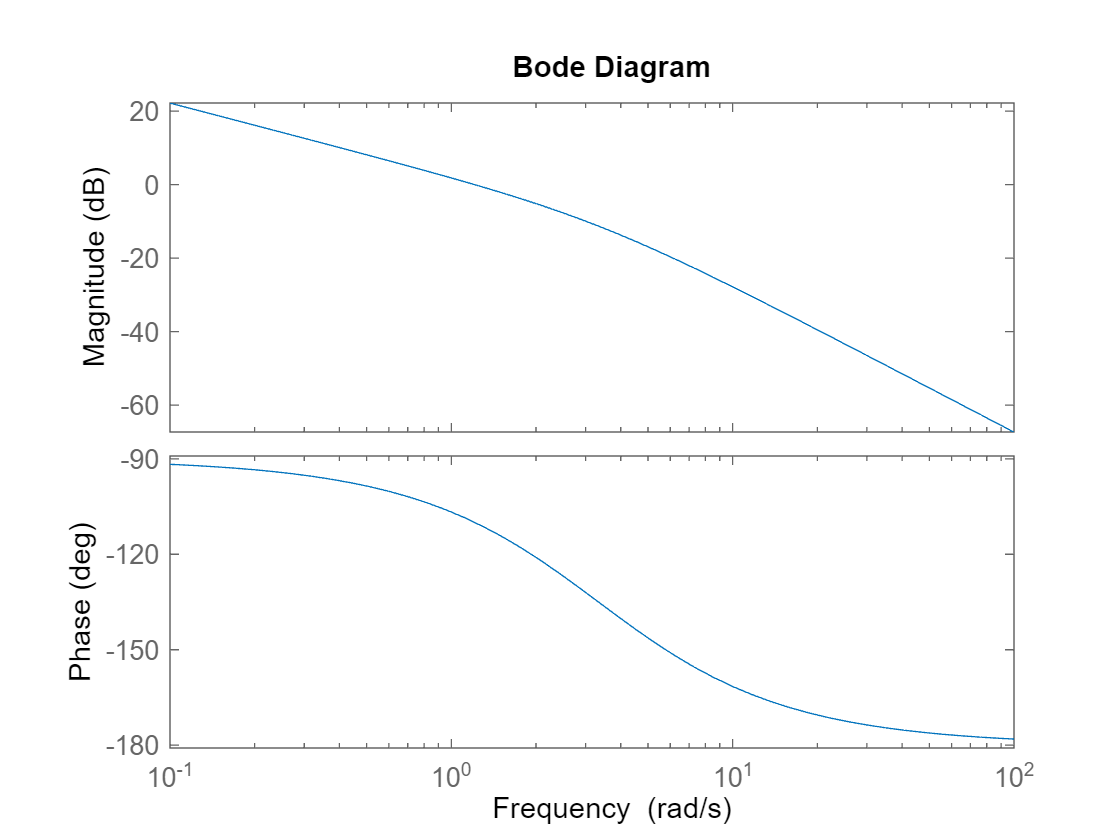

L = Kp * P;
close all
figure(1)
bode(L)

[~, phim, ~, wgc] = margin(L)

phim = 70.0396

wgc = 1.2106

wgc1 = 2 * pi * 3;
[mag1, ph1] = bode(P, wgc1)

mag1 = 0.0259

ph1 = -169.9716

phm1 = ph1 + 180

phm1 = 10.0284

delta_phm = phim - phm1

delta_phm = 60.0111

Devo incrementare il margine di fase di 60°. Uso lo zero per alzare la fase e il guadagno Kp per traslare verticalmente il diagramma del modulo in modo da sistemare la pulsazione di attraversamento.

pid.Td = 0.9754 * wgc1 / 200;
[mag2, ph2] = bode((pid.Td * s + 1) * P, wgc1)

mag2 = 0.0518

ph2 = -109.9605

phm2 = ph2 + 180

phm2 = 70.0395

delta_phm2 = phim - phm2

delta_phm2 = 2.3775e-05

Con questa scelta di Td, il margine di fase in wgc1 è lo stesso. Scegliendo Kp come l'inverso del modulo in wgc1, il diagramma della fase non varia, mentre il diagramma del modulo viene traslato in modo che attraversi l'asse a 0 dB in wgc1.

pid.Kp = 1 / mag2;
C = pid.Kp * (pid.Td * s + 1);

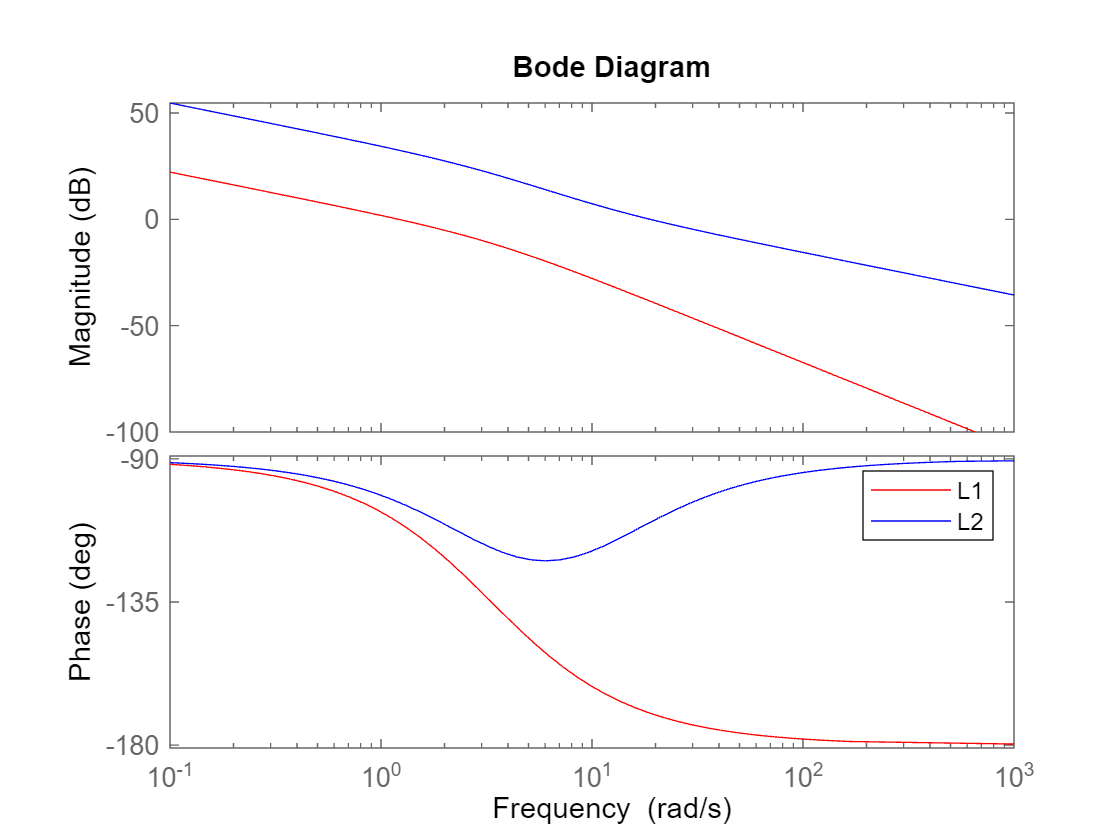

L2 = C * P;
close all
figure(2)
hold on
bode(L, "r")
bode(L2, "b")
legend("L1", "L2")

[~, phim2, ~, wgc2] = margin(L2)

phim2 = 70.0396

wgc2 = 18.8496

T1 = minreal(feedback(L, 1), 1e-6);
T2 = minreal(feedback(L2, 1), 1e-6);

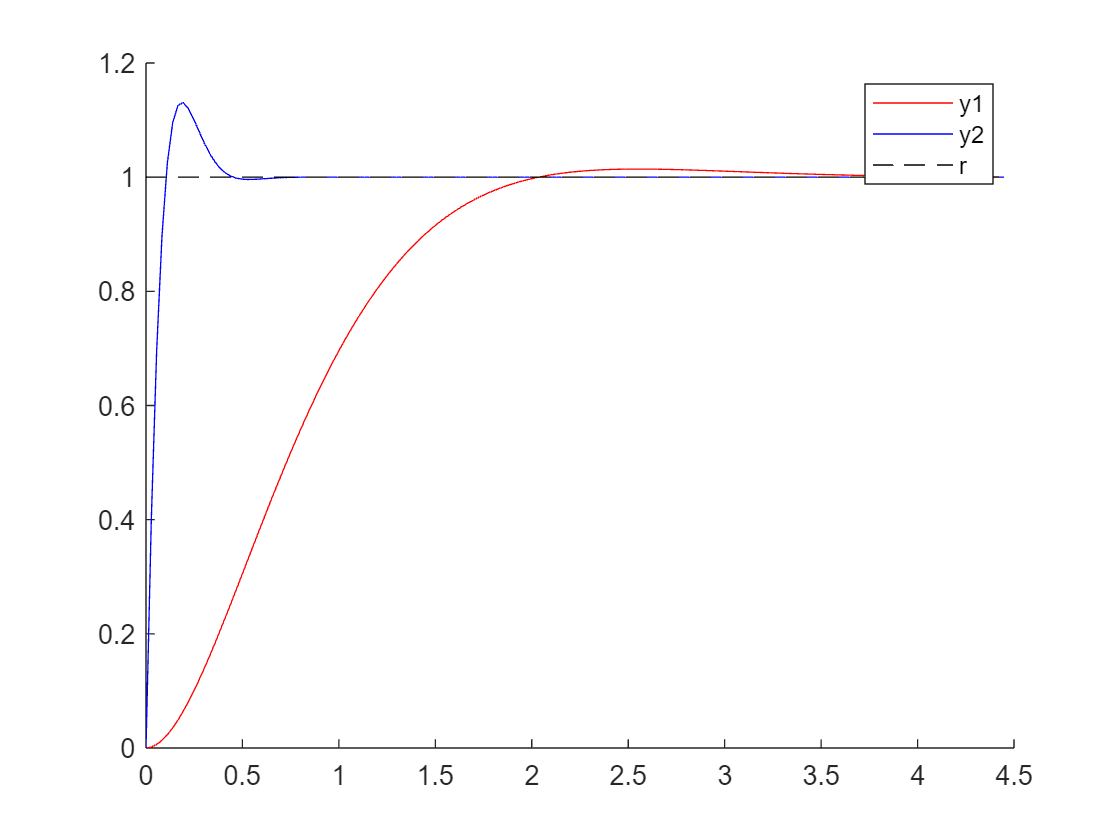

[y1, t1] = step(T1);
[y2, t2] = step(T2, t1);

close all
figure(3)
hold on
plot(t1, y1, "r")
plot(t2, y2, "b")
plot([t1(1), t1(end)], [1 1], "k--")
legend("y1", "y2", "r")

infos1 = stepinfo(T1, "SettlingTimeThreshold", 0.05);
infos2 = stepinfo(T2, "SettlingTimeThreshold", 0.05);
infos1.Overshoot

ans = 1.4216

infos2.Overshoot

ans = 13.1215

infos1.SettlingTime

ans = 1.6458

infos2.SettlingTime

ans = 0.3165

La funzione di trasferimento in catena aperta di entrambi i sistemi presenta un polo nell'origine, dunque, come si può anche vedere in figura, entrambi i sistemi riescono a inseguire in modo perfetto un riferimento a gradino.

D1 = minreal(P / (1 + Kp * P), 1e-6);
D2 = minreal(P / (1 + C * P), 1e-6);

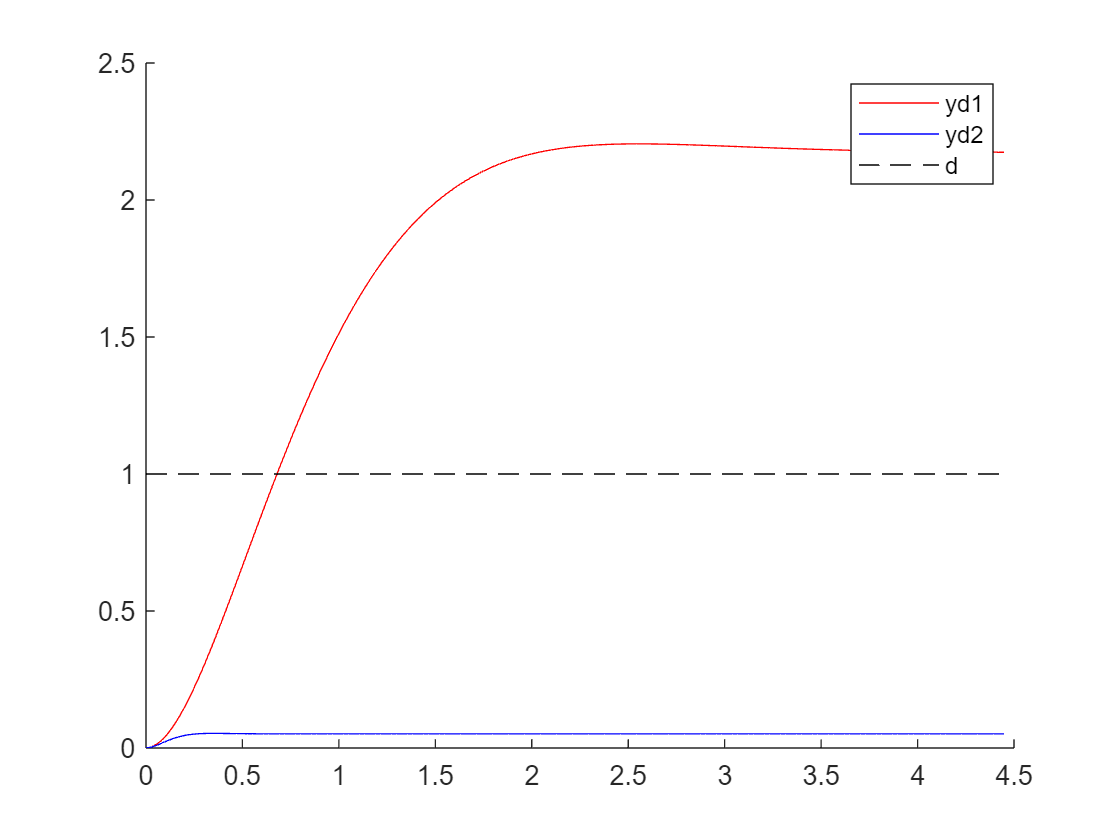

[yd1, td1] = step(D1);
[yd2, td2] = step(D2, td1);

close all
figure(4)
hold on
plot(td1, yd1, "r")
plot(td2, yd2, "b")
plot([td1(1), td1(end)], [1 1], "k--")
legend("yd1", "yd2", "d")

Nessuno dei due controllori contiene un polo nell'origine, dunque nessuno dei due riesce a reiettare completamente il disturbo di carico a gradino.

16.13